# **AdaBoost** Demo

**Choosen Weak classifiers:**

- ***GDA***

- ***Knn (NumNeighbors = 5)***

- ***Naive Bayes***

- ***Linear (Logistic Regression*)***

- ***SVM ('KernelFunction: rbf')***

## Initialization (Dataset:: NoisyData.csv)

data=csvread('NoisyData.csv');

- **Number of Data Points**

disp(length(data))

   400



- **CrossVal = ' Holdout '**

[trset,teset ] = holdout( data,70 );

- **Visulaization of mapped Data**

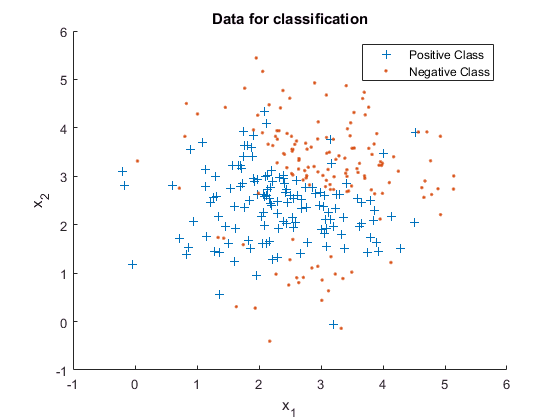

X=trset(:,1:end-1);Y=trset(:,end);
Xtest=teset(:,1:end-1);Ytest=teset(:,end);
figure
hold on
scatter(X(Y==1,1),X(Y==1,2),'+')
scatter(X(Y==-1,1),X(Y==-1,2),'.')
xlabel('{x_1}')
ylabel('{x_2}')
zlabel('{x_3}')
legend('Positive Class','Negative Class')
title('Data for classification')
hold off

- **For Decision Boundry plots**

[x1 x2]=meshgrid(min(X(:,1)):0.01:max(X(:,1)),min(X(:,2)):0.01:max(X(:,2)));
Xn=[reshape(x1,1,size(x1,2)*size(x1,1))' reshape(x2,1,size(x2,2)*size(x2,1))'];

## Gaussian Discriminant Analysis Classification

*Fit discriminant analysis classifier*

gda_in=fitcdiscr(X,Y);
gda_out=predict(gda_in, Xtest);

- ***Performance Measures***

[Fmeasure(1),Accuracy(1)] = confusion_mat(Ytest, gda_out);
Fmeasure_GDA=Fmeasure(1)

Fmeasure_GDA = 0.7903

Accuracy_GDA=Accuracy(1)

Accuracy_GDA = 0.7833

- ***Decision Boundry due to GDA***

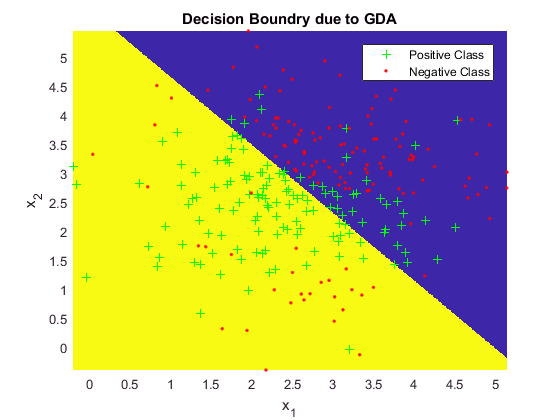

yn=predict(gda_in,Xn);
Yn=reshape(yn,size(x1));
DecisionBoundry( X,Y,Yn )
title('Decision Boundry due to GDA')

## Knn Classification 

- ***Number of Nearest Neighbors= 5***

knn_in=fitcknn(X,Y,'NumNeighbors',5);
knn_out=predict(knn_in, Xtest);

- ***Performance Measures***

[Fmeasure(2),Accuracy(2)] = confusion_mat(Ytest, knn_out);
Fmeasure_knn=Fmeasure(2)

Fmeasure_knn = 0.9048

Accuracy_knn=Accuracy(2)

Accuracy_knn = 0.9000

- ***Decision Boundry due to knn***

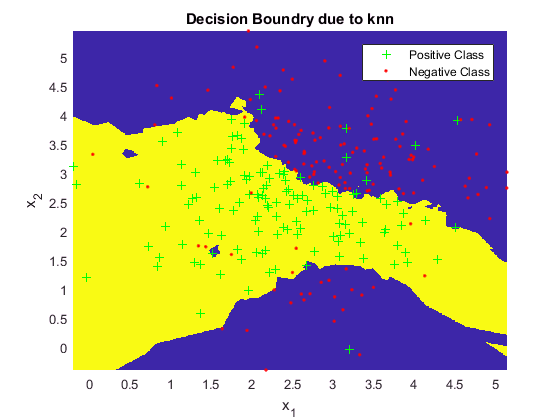

yn=predict(knn_in,Xn);
Yn=reshape(yn,size(x1));
DecisionBoundry( X,Y,Yn )
title('Decision Boundry due to knn')

## Naive Bayes Classification

*Train multiclass naive Bayes model*

nb_in=fitcnb(X,Y);
nb_out=predict(nb_in, Xtest);

- ***Performance Measures***

[Fmeasure(3),Accuracy(3)] = confusion_mat(Ytest, nb_out);
Fmeasure_NB=Fmeasure(3)

Fmeasure_NB = 0.8730

Accuracy_NB=Accuracy(3)

Accuracy_NB = 0.8667

- ***Decision Boundry due to Naive bayes***

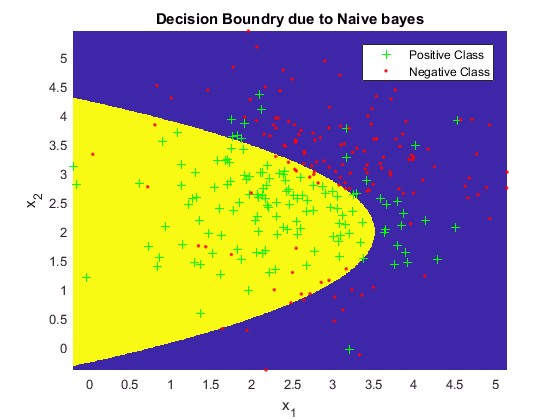

yn=predict(nb_in,Xn);
Yn=reshape(yn,size(x1));
DecisionBoundry( X,Y,Yn)
title('Decision Boundry due to Naive bayes')

## Logistic Regression

`fitclinear`* trains linear classification models for two-class (binary) learning with high-dimensional, full or sparse predictor data.*

linear_in=fitclinear(X,Y,'Learner','logistic');
linear_out=predict(linear_in, Xtest);

- ***Performance Measures***

[Fmeasure(4),Accuracy(4)] = confusion_mat(Ytest, linear_out);
Fmeasure_Linear=Fmeasure(4)

Fmeasure_Linear = 0.8000

Accuracy_Linear=Accuracy(4)

Accuracy_Linear = 0.7917

- ***Decision Boundry due to Logistic regression***

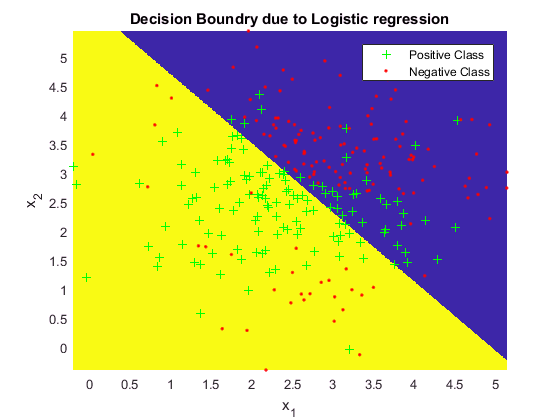

yn=predict(linear_in,Xn);
Yn=reshape(yn,size(x1));
DecisionBoundry( X,Y,Yn )
title('Decision Boundry due to Logistic regression')

## SVM (rbf) Classification

svm_in=fitcsvm(X,Y,'KernelFunction','rbf');
svm_out=predict(svm_in, Xtest);

- ***Performance Measures***

[Fmeasure(5),Accuracy(5)] = confusion_mat(Ytest, svm_out);
Fmeasure_svm=Fmeasure(5)

Fmeasure_svm = 0.9219

Accuracy_svm=Accuracy(5)

Accuracy_svm = 0.9167

- ***Decision Boundry due to SVM (rbf)***

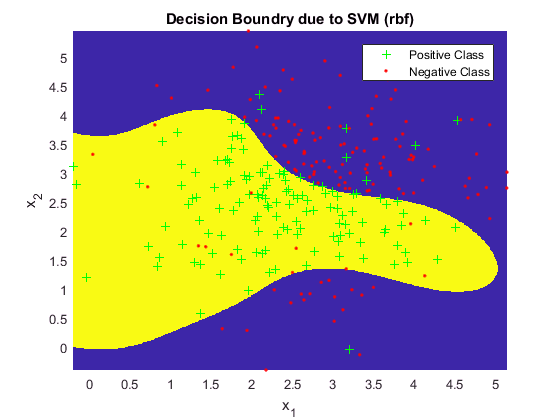

yn=predict(svm_in,Xn);
Yn=reshape(yn,size(x1));
DecisionBoundry( X,Y,Yn)
title('Decision Boundry due to SVM (rbf)')

## - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - -

## | Adaboost (GDA, Knn, NB, Logistic, SVM) |

## - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - -

% Choose best in maxItr number of iterations
maxItr=50;
fm_=[];

for itr=1:maxItr
    [~,ada_test(:,itr)]= adaboost(X,Y, Xtest);
    fm_=[fm_; confusion_mat(Ytest, ada_test(:,itr))];
end

[fm itr]=max(fm_);
ada_out=ada_test(:,itr);

- ***Performance Measures***

[Fmeasure(6),Accuracy(6)] = confusion_mat(Ytest, ada_out);
Fmeasure_AdaBoost=Fmeasure(6)

Fmeasure_AdaBoost = 0.9385

Accuracy_AdaBoost=Accuracy(6)

Accuracy_AdaBoost = 0.9333

- ***Decision Boundry due to AdaBoost***

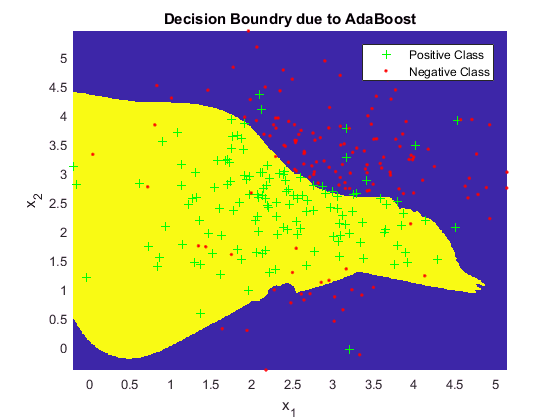

[~,yn]=adaboost(X,Y,Xn);
Yn=reshape(yn,size(x1));
DecisionBoundry( X,Y,Yn )
title('Decision Boundry due to AdaBoost')

## Conclusion:

Curve Below reveals that by using AdaBoost concepts,improves  performance.

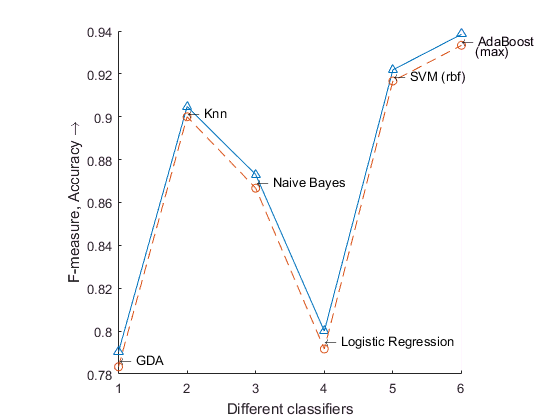

figure
hold on
plot(Fmeasure,'-^')
plot(Accuracy,'--o')
text(1,0.5*(Fmeasure(1)+Accuracy(1)),'\leftarrow GDA')
text(2,0.5*(Fmeasure(2)+Accuracy(2)),'\leftarrow Knn')
text(3,0.5*(Fmeasure(3)+Accuracy(3)),'\leftarrow Naive Bayes')
text(4,0.5*(Fmeasure(4)+Accuracy(4)),'\leftarrow Logistic Regression')
text(5,0.5*(Fmeasure(5)+Accuracy(5)),'\leftarrow SVM (rbf)')
text(6,0.5*(Fmeasure(6)+Accuracy(6)),'\leftarrow AdaBoost')
text(6,0.992*Fmeasure(6),'    (max)')
axis square
xlabel('Different classifiers')
ylabel('F-measure, Accuracy \rightarrow')
hold off

% created by Bhartendu, Machine Learning & Computing 

[Bhartendu, Machine Learning & Computing, Mathworks File Exchange](https://in.mathworks.com/matlabcentral/profile/authors/10083740-bhartendu)